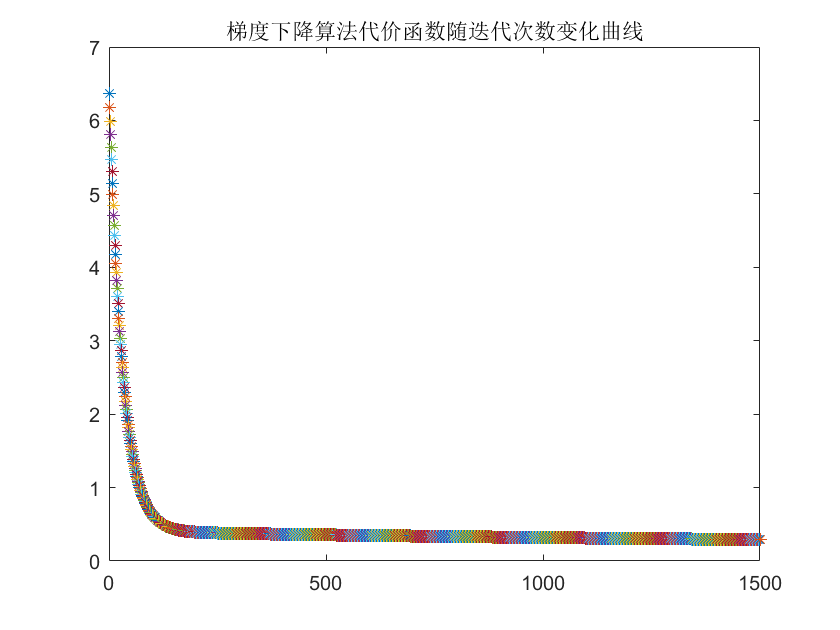

clc;clear;
n=2;%特征数量
theta=zeros(3,1);
data=load('ex1data2.txt');
x=data;
x(:,3)=[];
y=data(:,3);
derta=zeros(3,1);
m=length(data);%样本数量
%特征缩放很必要，否则得不出正确结果
x(:,1)=x(:,1)/1000;
y=y/100000;

alpha=0.001;
for k=1:1500
    for i=1:m
      %注意两个矩阵相乘的顺序千万不要弄反
      %利用了笔记上4.1节和5.5节的公式
      derta=derta+([1,x(i,:)]*theta-y(i))*([1,x(i,:)])';
    end
    derta=derta/m;
    theta=theta-alpha*derta;
    J=0;
    for j=1:m
        J=J+([1,x(j,:)]*theta-y(j))^2;
    end
    J=J/(2*m);
    plot(k,J,'*');
    title('梯度下降算法代价函数随迭代次数变化曲线')
    hold on
end

fprintf('利用梯度下降算法预测1650平方英尺的三居室房子价格为：%f$',[1,1.650,3]*theta*100000)

利用梯度下降算法预测1650平方英尺的三居室房子价格为：302931.071997$


% 正规方程解法
x=data;
x(:,3)=[];
x=[ones(m,1),x];
y=data(:,3);
theta_z=pinv(x'*x)*x'*y;
fprintf('利用正规方程预测1650平方英尺的三居室房子价格为：%f$',[1,1650,3]*theta_z)

利用正规方程预测1650平方英尺的三居室房子价格为：293081.464335$